## Covariance Matrix Demonstration

Use a 16-element ULA with 10 GHz spacing.

fc = 10e9;
spacing = freq2wavelen(fc)/2;
elementgrid = [4 4];
nelements = prod(elementgrid);
ula = phased.ULA(NumElements=nelements,ElementSpacing=spacing);

Next create a receiver with 10 dB noise figure.

receiver = phased.Receiver(Gain=20,...
    NoiseMethod="Noise figure",NoiseFigure=10,ReferenceTemperature=300);

## Noise Only Covariance Matrix

First we investigate the covariance matrix when there is only noise present in the received signal.

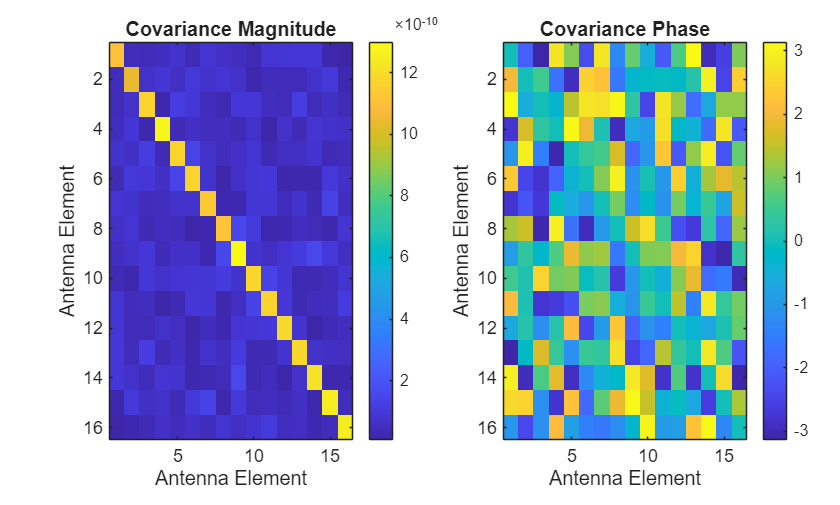

nSamples = 310;
sig = zeros(nSamples,nelements);
noiserx = receiver(sig);
helperPlotCovariance(noiserx);

## Single Signal Covariance Matrix

Next we investigate the covariance matrix when there is a signal arriving at some angle of arrival.

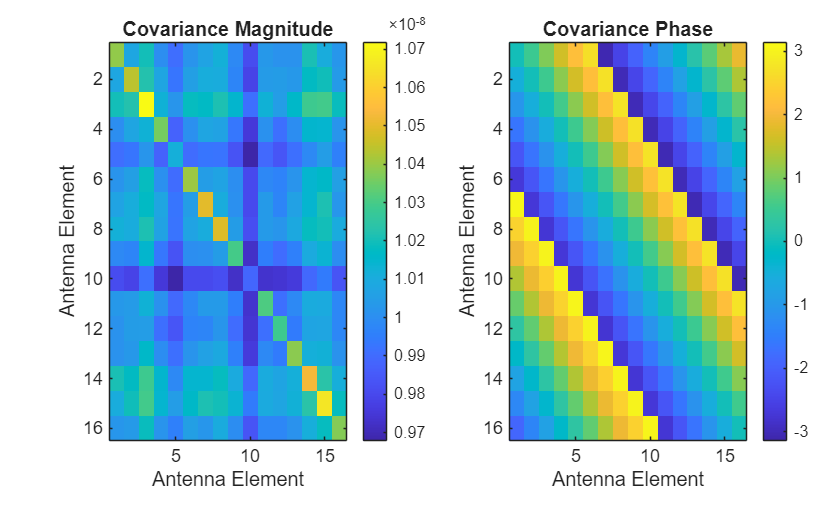

angOfArrival = 10;
signalMagnitude = 1e-6;
nSamples = 100;
sig = signalMagnitude*exp(1i*2*pi*rand(nSamples,1));
sigrx = collectPlaneWave(ula,sig,[angOfArrival;0],fc);
sigrx = receiver(sigrx);
helperPlotCovariance(sigrx)

## Modeling Transmitter Polarization

Demonstrate what effects we can capture by modeling polarization that are missed with the current model.

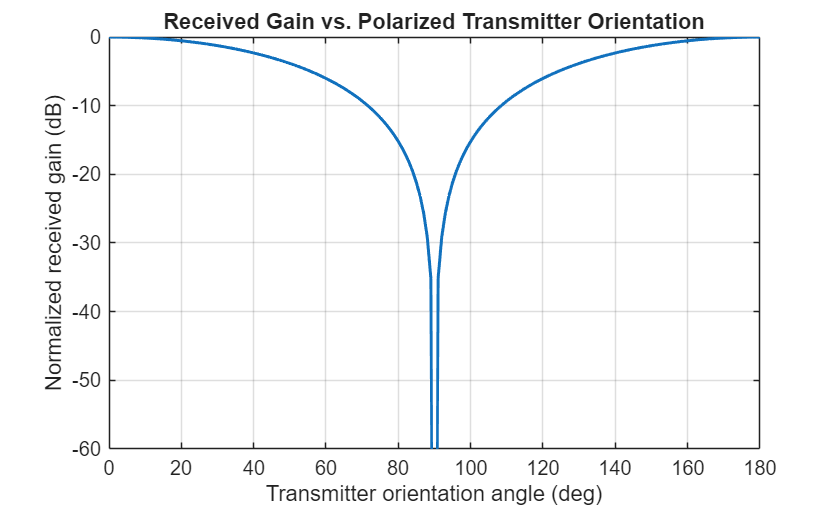

% Sweep TX orientation using laxes and plot received gain

clear; clc; close all;

fc = 10e9;
fs = 1e6;

t = (0:999).'/fs;
x = exp(1j*2*pi*50e3*t);

rxPos = [0; 0; 0];
txPos = [5; 0; 0];

txVel = [0; 0; 0];
rxVel = [0; 0; 0];

txAnt = phased.ShortDipoleAntennaElement( ...
    "FrequencyRange",[fc/2 fc*2], ...
    "AxisDirection","Z");

rxAnt = phased.ShortDipoleAntennaElement( ...
    "FrequencyRange",[fc/2 fc*2], ...
    "AxisDirection","Z");

tx = phased.Radiator( ...
    "Sensor",txAnt, ...
    "OperatingFrequency",fc, ...
    "CombineRadiatedSignals",true, ...
    "Polarization","Combined");

rx = phased.Collector( ...
    "Sensor",rxAnt, ...
    "OperatingFrequency",fc, ...
    "Polarization","Combined");

channel = phased.FreeSpace( ...
    "SampleRate",fs, ...
    "OperatingFrequency",fc, ...
    "TwoWayPropagation",false);

[~,txAng] = rangeangle(rxPos,txPos);
[~,rxAng] = rangeangle(txPos,rxPos);

% Receiver stays fixed
rxLaxes = eye(3);

% Rotate TX local axes about global X axis.
% This rotates the TX dipole local Z-axis from global Z toward global Y.
theta = 0:1:180;
rxGain = zeros(size(theta));

for k = 1:numel(theta)
    th = theta(k);
    txLaxes = rotx(th);
    txField = tx(x,txAng,txLaxes);
    propagatedField = channel( ...
        txField,txPos,rxPos,txVel,rxVel);
    y = rx(propagatedField,rxAng,rxLaxes);
    rxGain(k) = mean(abs(y));
end

rxGain_dB = mag2db(rxGain / max(rxGain));

ax = axes(figure);
plot(ax,theta,rxGain_dB,"LineWidth",1.5);
grid(ax,"on");
xlabel(ax,"Transmitter orientation angle (deg)");
ylabel(ax,"Normalized received gain (dB)");
title(ax,"Received Gain vs. Polarized Transmitter Orientation");
ylim(ax,[-60 0]);

## Free Space Loss

Free Space Path Loss is only valid in the far field. The following plot shows free space path loss as a function of distance for a signal at our wavelength.

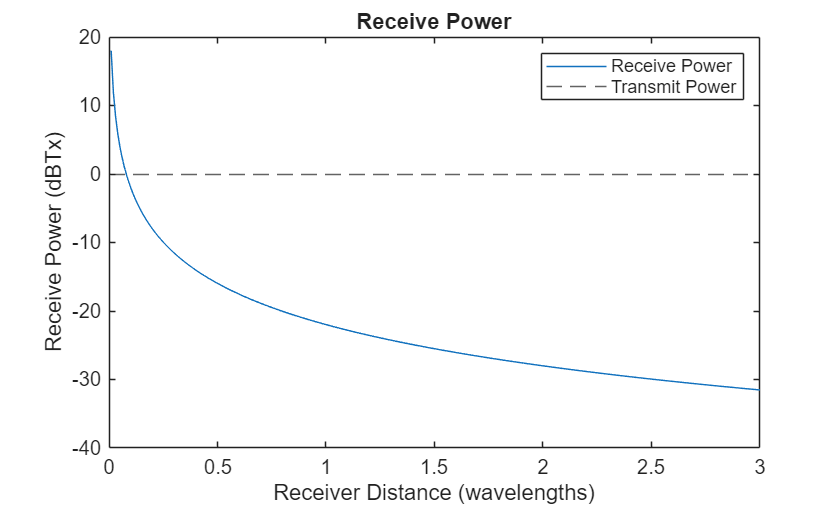

lambda = 1;
d = 0:lambda/100:lambda*3;
txpower = 1;
fspl = (4*pi*d/lambda).^2;
rxpower = (lambda./(4*pi*d)).^2*txpower;
ax = axes(figure);
plot(ax,d,pow2db(rxpower),DisplayName='Receive Power');
yline(ax,0,LineStyle='--',DisplayName='Transmit Power');
title(ax,'Receive Power');
ylabel(ax,'Receive Power (dBTx)');
xlabel(ax,'Receiver Distance (wavelengths)');
legend(ax);

## Multipath

We can use the phased.ScatteringMIMOChannel to create multipath effects.

tx = phased.IsotropicAntennaElement;
fc = 10e9;
spacing = freq2wavelen(fc)/2;
rx = phased.URA(Size=[4 4],ElementSpacing=spacing);
sig = rand(1000,1,like=1i);
channel = phased.ScatteringMIMOChannel(TransmitArray=tx,ReceiveArray=rx,CarrierFrequency=fc,SimulateDirectPath=true,...
    TransmitArrayPosition=[0;0;0],ReceiveArrayPosition=[10;0;0],NumScatterers=10,ScattererPositionBoundary=[0 10]);
out = channel(sig);

If we try to perform MUSIC with substantial multipath effects, the results are poor.

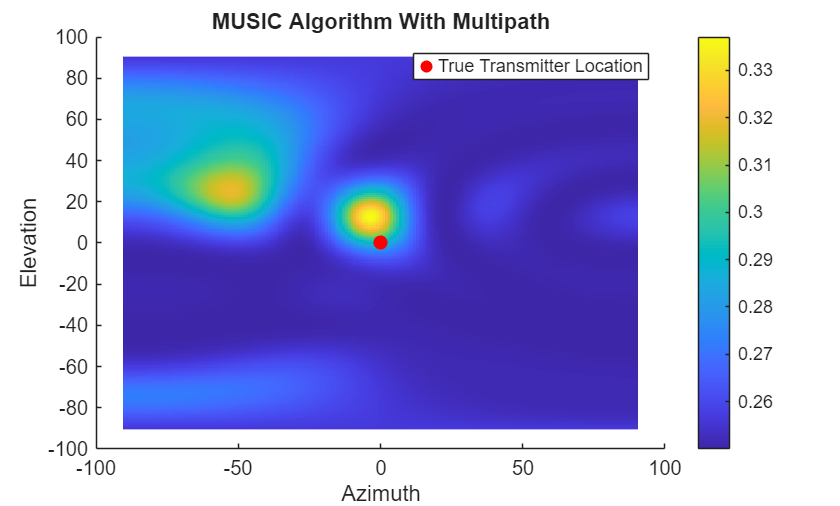

music = phased.MUSICEstimator2D(SensorArray=rx,OperatingFrequency=fc,AzimuthScanAngles=-90:90,ElevationScanAngles=-90:90,NumSignalsSource="Property",NumSignals=1);
musicspec = music(out);
ax = axes(figure);
helperPlotMUSICSpectrum(ax,music,musicspec,[0;0],'MUSIC Algorithm With Multipath');

## Mutual Coupling

In this section, we create antenna models with and without mutual coupling and compare the results of the MUSIC algorithm.

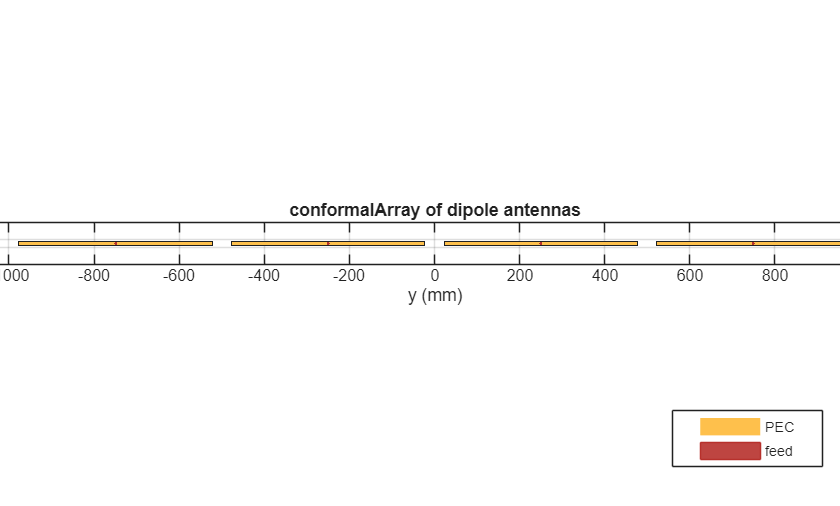

fc = 3e8;
lambda = freq2wavelen(fc);
M = 4;
spacing = lambda/2;
antennapos = [zeros(1,M);(-(M-1)/2:(M-1)/2)*spacing;zeros(1,M)];
d = dipole(Length=lambda/2.2,Width=lambda/100,Tilt=90);
array = conformalArray(Element=repmat(d,1,M),ElementPosition=antennapos');
figure;
show(array);
view([90 0]);
zlim([-50 50]);

The manifold is simulated using the `helperGenerateArrayManifold` function. The output of this function is an object called a `helperArrayManifold`, which stores the simulated measurements.

fmeas = 3e8;
azmeas = -90:90;
elmeas = 0;
arraymanifold = helperGenerateArrayManifold(array,fmeas,azmeas,elmeas);

To demonstrate the workflow, we simulate signals impinging on the array using the same approach that was used to measure the array manifold. This makes the example internally consistent because both the manifold and the signals are derived from the same electromagnetic model.

In this example, we have two signals arriving from different directions.

% Number of samples in signal
nSamples = 1e5;

% Carrier frequency of both signals is 3e8
fc = 3e8;

% Signals are randomly generated
nSig = 2;
sig = randn(nSamples,nSig,like=1i);

% Angle of arrival
ang = [43 -12;0 0];

% Receiver used to add noise
rx = phased.Receiver(NoiseFigure=20);

% Collect received signal and add noise
sigcollect = helperCollectSignal(array,sig,fc,ang);
sigrx = rx(sigcollect);

In practice, you can replace the simulated snapshot with your recorded array data, and the processing remains unchanged.

### MUSIC

MUSIC is a commonly used super-resolution DOA algorithm. For more information on the MUSIC algorithm, see [MUSIC Super-Resolution DOA Estimation](docid:phased_ug#bvdn4ja).

The effectiveness of the MUSIC algorithm relies heavily on having an accurate representation of the array response based on the true signal DOA, which is why measuring the true array manifold may be beneficial in high precision applications.

The first step in the MUSIC algorithm is generating the sample covariance matrix based on the signal collected in the prior section.

scov = cov(sigrx);

The next step is calculating the eigenvectors and eigenvalues of the sample covariance matrix.

[v,ev] = eig(scov);
ev = diag(ev);

Noise eigenvectors correspond to the lowest magnitude eigenvalues. We assume knowledge of the number of signals present to retrieve the noise eigenvectors. Use the noise eigenvectors to generate the noise subspace.

[~,dIdx] = sort(ev);
noiseIdx = dIdx(1:(M-nSig));
vNoise = v(:,noiseIdx);
noiseSubspace = vNoise*vNoise';

Once the noise subspace is calculated, we need to use information about the array manifold to generate the MUSIC pseudo-spectrum. We generate the steering vectors across a grid of azimuths and elevations to do so.

% Define the search space
azSearch = -90:90;
nAz = length(azSearch);
elSearch = 0;
nEl = length(elSearch);

% Initialize the pseudo-spectrum for the measured manifold
musicSpectrum = zeros(nAz,nEl);

% Calculate pseudo-spectrum across search space using the measured array
% manifold
for iAz = 1:nAz
    for iEl = 1:nEl
        % Calculate the steering vector from the array manifold
        azmeas = azSearch(iAz);
        elmeas = elSearch(iEl);
        sv = steeringVector(arraymanifold,fc,azmeas,elmeas);

        % Generate the MUSIC pseudo-spectrum at the given az-el for the
        % measured antenna manifold
        musicSpectrum(iAz,iEl) = 1/(sv*noiseSubspace*sv');
    end
end

We can also perform MUSIC estimation without modeling mutual coupling by inserting the dipole into a phased.ULA:

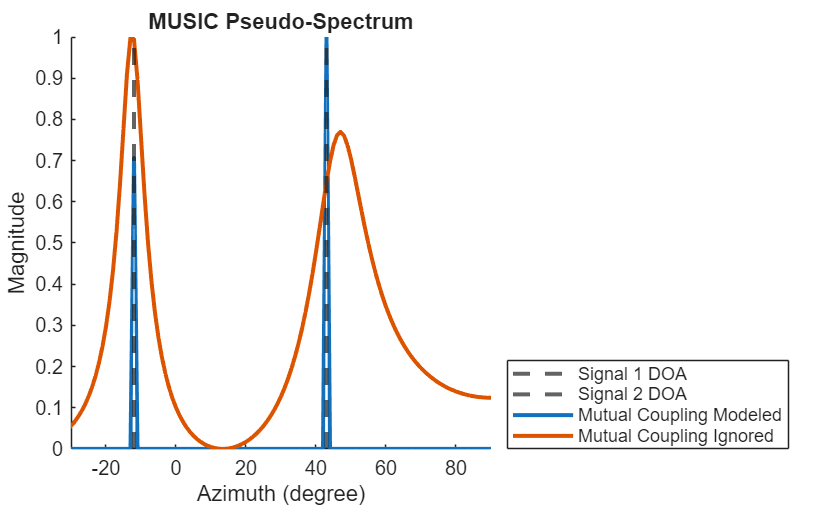

isoArray = phased.ULA(Element=d,NumElements=4,ElementSpacing=spacing);
musicest = phased.MUSICEstimator(SensorArray=isoArray,NumSignalsSource="Property",NumSignals=nSig,OperatingFrequency=fc,ScanAngles=azSearch);
isomusicest = musicest(sigrx);

% Update the music spectra so that they span the same range
mcmusic = abs(musicSpectrum)/max(abs(musicSpectrum));
isomusic = db2mag(flip(isomusicest-max(isomusicest))); % Need to figure out what's happening here, why flip?

% Stretch the spectrum to make them the same scale
mcmusic = (mcmusic-min(mcmusic))/(max(mcmusic)-min(mcmusic));
isomusic = (isomusic-min(isomusic))/(max(isomusic)-min(isomusic));

% Plot the music spectrum with and without mutual coupling modeled
ax = axes(figure);
hold(ax,"on");
xline(ax,ang(1,1),LineStyle="--",DisplayName='Signal 1 DOA',LineWidth=2);
xline(ax,ang(1,2),LineStyle="--",DisplayName='Signal 2 DOA',LineWidth=2);
plot(ax,azSearch,mcmusic,DisplayName="Mutual Coupling Modeled",LineWidth=2);
plot(ax,azSearch,isomusic,DisplayName="Mutual Coupling Ignored",LineWidth=2);
title(ax,'MUSIC Pseudo-Spectrum');
xlabel(ax,'Azimuth (degree)');
ylabel(ax,'Magnitude');
legend(ax,location="southeastoutside");
xlim(ax,[-30 90]);

## Helper Functions

function helperPlotCovariance(sig)
    samplecov = sig'*sig;
    tl = tiledlayout(figure,"horizontal");
    magax = nexttile(tl);
    phaseax = nexttile(tl);
    
    % Plot covariance magnitude
    imagesc(magax,abs(samplecov));
    colorbar(magax);
    title(magax,'Covariance Magnitude');
    ylabel(magax,'Antenna Element');
    xlabel(magax,'Antenna Element');

    % Plot covariance phase
    imagesc(phaseax,angle(samplecov));
    colorbar(phaseax);
    title(phaseax,'Covariance Phase');
    ylabel(phaseax,'Antenna Element');
    xlabel(phaseax,'Antenna Element');
    clim(phaseax,[-pi pi])
end

function manifold = helperGenerateArrayManifold(sensor,f,az,el)
    % Measure receive manifold from Comparison of Antenna Array Transmit and Receive Manifold

    % We measure response at each frequency, azimuth, and elevation
    if isprop(sensor,'Element')
        nElements = length(sensor.Element);

        % Setup the array elements
        nomLoad = lumpedElement(Impedance=[]);
        for m=1:nElements
            sensor.Element(m).Load = nomLoad;
        end
    else
        nElements = 1;
        nomLoad = lumpedElement(Impedance=[]);
        sensor.Load = nomLoad;
    end

    nFreq = length(f);
    nAzimuth = length(az);
    nElevation = length(el);
    nMeasurements = nAzimuth*nElevation*nFreq;

    % Initialize data storage
    azMeasurement = zeros(nMeasurements,1);
    elMeasurement = zeros(nMeasurements,1);
    freqMeasurement = zeros(nMeasurements,1);
    manifoldMeasurement = zeros(nAzimuth*nElevation*nFreq,nElements);

    % Calculate the response at each azimuth, elevation, and frequency
    idx = 1;
    for cAz = az
        for cEl = el
            for cFreq = f
                % Measure far field response
                erx = helperMeasureFarField(sensor,cAz,cEl,cFreq);

                % Save the measurement values
                azMeasurement(idx) = cAz;
                elMeasurement(idx) = cEl;
                freqMeasurement(idx) = cFreq;

                % Add some noise to make the measurement more realistic
                %manifoldMeasurement(idx,:) = awgn(erx,50,pow2db(rms(erx)^2));
                manifoldMeasurement(idx,:) = erx;

                idx = idx + 1;
            end
        end
    end

    manifold = helperArrayManifold(manifoldMeasurement,freqMeasurement,azMeasurement,elMeasurement);
end

function sigout = helperCollectSignal(array,sigin,f,ang)
    % Collect signal with carrier frequency f

    % Initialize data storage
    nElements = length(array.Element);
    nSample = size(sigin,1);
    nSigIn = size(sigin,2);

    % Initialize data storage
    sigout = zeros(nSample,nElements);

    % Setup the array elements
    nomLoad = lumpedElement(Impedance=[]);
    for m=1:nElements
        array.Element(m).Load = nomLoad;
    end
    
    % Calculate the reception of each signal
    for iSig = 1:nSigIn
        % Get current signal and angle of arrival
        cSig = sigin(:,iSig);
        cAz = ang(1,iSig);
        cEl = ang(2,iSig);

        erx = helperMeasureFarField(array,cAz,cEl,f);

        % Get the output signal
        sigout = sigout + erx.*cSig;
    end
end

function sv = helperMeasureFarField(array,az,el,f)
    % Calculate direction and polarization vector
    [x,y,z] = sph2cart(deg2rad(az),deg2rad(el),1);
    dirVec = [x;y;z];
    polVec = getPolVec(dirVec);
    
    % Measure the response
    p = planeWaveExcitation(Element=array,Direction=dirVec,Polarization=polVec);
    sv = feedCurrent(p,f);
end

function polVec = getPolVec(dirVec)
    % In this example, we calculate the polarization vector by projecting
    % the x unit vector onto the space orthogonal to the direction vector.
    % If the direction vector points in the x direction, set it to [1 0 0]
    % by default.
    k = [0;1;0];
    orthProj = k - dot(k,dirVec)/dot(dirVec,dirVec)*dirVec;
    if norm(orthProj) < sqrt(eps)
        polVec = [0;0;1];
    else
        polVec = orthProj / norm(orthProj);
    end
end

function ang = getAngle(v1,v2)
    ang = acosd(abs(v1*v2')/(norm(v1)*norm(v2)));
end